# Presentación Final (Cinemática Diferencial de Piernas)

A01798275 Bruno Manuel Zamora Garcia

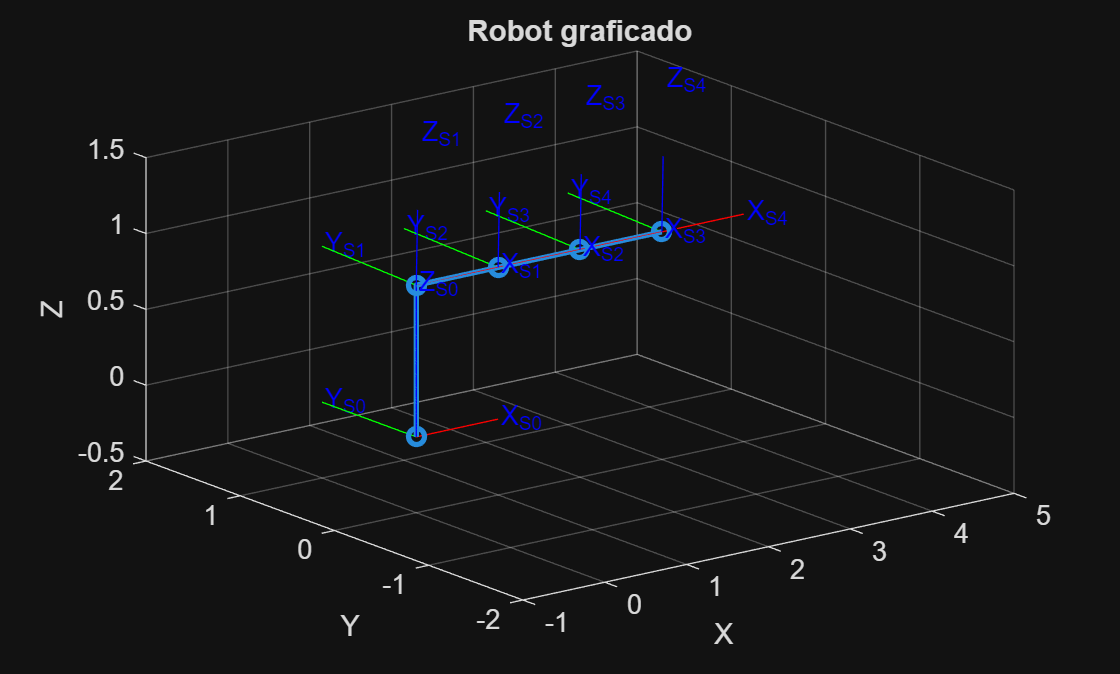

clear all
close all
clc

% Inicialización de la escena 3D, incluyendo la limpieza de variables, cierre de ventanas y consola.

H0 = SE3();  % Definición del marco de referencia base utilizando la matriz identidad.

% Definición de transformaciones relativas entre marcos consecutivos.
% Cada transformación representa una articulación o eslabón del robot.

H1 = SE3(rotx(pi/2), [0 0 1]);  % Rotación de 90° en X y traslación unitaria en Z.
H2 = SE3(rotz(0), [1 0 0]);     % Sin rotación, traslación unitaria en X (eslabón horizontal).
H3 = SE3(rotz(0), [1 0 0]);     % Repite la traslación en X hacia el siguiente marco.
H4 = SE3(rotz(0), [1 0 0]);     % Última traslación horizontal, sin rotación.

% Cálculo de las transformaciones homogéneas acumuladas con respecto al sistema base.
H0_1 = H0 * H1;
H1_2 = H0_1 * H2;
H2_3 = H1_2 * H3;
H3_4 = H2_3 * H4;

% Extracción de las posiciones de los marcos desde las matrices SE3 (columna de traslación).
p0 = transl(H0);
p1 = transl(H0_1);
p2 = transl(H1_2);
p3 = transl(H2_3);
p4 = transl(H3_4);

% Se agrupan las coordenadas de todos los puntos para graficar la trayectoria de la estructura.
X = [p0(1) p1(1) p2(1) p3(1) p4(1)];
Y = [p0(2) p1(2) p2(2) p3(2) p4(2)];
Z = [p0(3) p1(3) p2(3) p3(3) p4(3)];

% Se genera la gráfica tridimensional de la estructura del robot.
plot3(X, Y, Z, '-o', 'LineWidth', 2, 'MarkerSize', 6);
axis ([-1 5 -2 2 -0.5 1.5]); grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Robot graficado');

% Visualización de cada uno de los marcos de coordenadas utilizando trplot.
% Esto permite identificar gráficamente la orientación y posición de cada trama.
hold on
trplot(H0,    'rgb', 'frame', 'S0');
trplot(H0_1,  'rgb', 'frame', 'S1');
trplot(H1_2,  'rgb', 'frame', 'S2');
trplot(H2_3,  'rgb', 'frame', 'S3');
trplot(H3_4,  'rgb', 'frame', 'S4');
hold off